clc;
clear;
%% 基础参数
popSize = 200;  %种群内个体数目
N_chrom = 1; %染色体节点数，也就是每个个体有多少条染色体，其实说白了就是看适应函数里有几个自变量。
iter = 1000; %迭代次数，也就是一共有多少代
C = [3200 2800 2800 2900 0;3200 3400 3900 2880 0;20500 26000 31000 0 0;3200 3600 4100 2680 0;870 1500 1800 0 0;1850 1900 2070 1900 1650];     % 成本
W = [0.141; 0.195; 0.139; 0.188; 0.151; 0.195];     % 权重
S = [1 0 0 0 0;1 1 0.556 0.0462 0;0.438 1 0.75 0 0;1 1 0.938 0.36 0;0.319 1 0.75 0 0;1 1 0.969 1 0.438];     % 模块隶属度
g = [1 1 0 0 0;0 0 1 0 0;0 0 0 1 0;0 1 0 0 1;0 0 0 1 0;1 0 1 0 0];
mut = 0.2;  %突变概率
acr = 0.2; %交叉概率
N = 6;                      % 行数
M = 5;                      % 列数
best = 1;
chrom_range = [-10 -10;10 10];%每个节点的值的区间
chrom = zeros(popSize, N_chrom);%存放染色体的矩阵
fitness = zeros(popSize, 1);%存放染色体的适应度
fitness_ave = zeros(1, iter);%存放每一代的平均适应度
fitness_best = zeros(1, iter);%存放每一代的最优适应度
chrom_best = zeros(1, N_chrom+1);%存放当前代的最优染色体与适应度
% 初始化，这只是用于生成第一代个体，并计算其适应度函数
chrom = Initialize(popSize, N_chrom, chrom_range); %初始化染色体
fitness = CalFitness(chrom, popSize, N_chrom); %计算适应度

M = 5

chrom_best = FindBest(chrom, fitness, N_chrom); %寻找最优染色体
fitness_best(1) = chrom_best(end); %将当前最优存入矩阵当中
fitness_ave(1) = CalAveFitness(fitness); %将当前平均适应度存入矩阵当中
%% 用于生成以下其余各代，一共迭代多少步就一共有多少代
for t = 2:iter
    chrom = MutChrom(chrom, mut, popSize, N_chrom, chrom_range, t, iter); %变异
    chrom = AcrChrom(chrom, acr, popSize, N_chrom); %交叉
    fitness = CalFitness(chrom, popSize, N_chrom); %计算适应度
    chrom_best_temp = FindBest(chrom, fitness, N_chrom); %寻找最优染色体
    if chrom_best_temp(end)>chrom_best(end) %替换掉当前储存的最优
        chrom_best = chrom_best_temp;
    end
    %%替换掉最劣
    [chrom, fitness] = ReplaceWorse(chrom, chrom_best, fitness);
    fitness_best(t) = chrom_best(end); %将当前最优存入矩阵当中
    fitness_ave(t) = CalAveFitness(fitness); %将当前平均适应度存入矩阵当中
end

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

M = 5

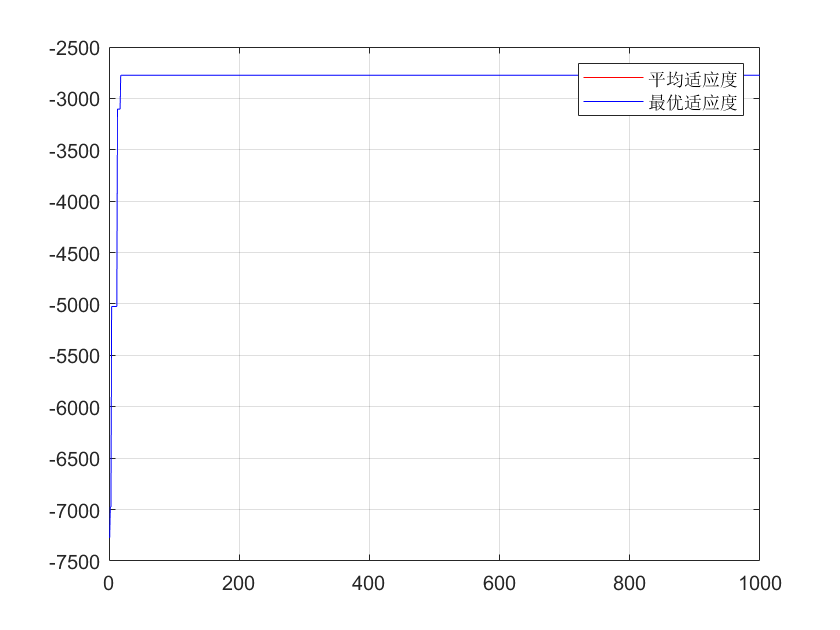

%% 作图
figure(1)
plot(1:iter, fitness_ave, 'r', 1:iter, fitness_best, 'b')
grid on
legend('平均适应度', '最优适应度')

suoe=PlotModel(chrom_best);

索引超出数组元素的数目(2)。

出错 xiugai>PlotModel (line 161)
z = chrom(3);

%% 输出结果
disp(['最优染色体为', num2str(chrom_best(1:end-1))])
disp(['最优适应度为', num2str(chrom_best(end))])

function chrom_new = Initialize(popSize, N_chrom, chrom_range)
chrom_new = rand(popSize, N_chrom);
for i = 1:N_chrom %每一列乘上范围
    chrom_new(:, i) = chrom_new(:, i)*(chrom_range(2, i)-chrom_range(1, i))+chrom_range(1, i);
end
end
 function fitness = CalFitness(pop, popSize, M, N, W, S, g, C)
    fitness = zeros(popSize, 1);
W = [0.141; 0.195; 0.139; 0.188; 0.151; 0.195];     % 权重
C = [3200 2800 2800 2900 0;3200 3400 3900 2880 0;20500 26000 31000 0 0;3200 3600 4100 2680 0;870 1500 1800 0 0;1850 1900 2070 1900 1650];     % 成本
W = [0.141; 0.195; 0.139; 0.188; 0.151; 0.195];     % 权重
S = [1 0 0 0 0;1 1 0.556 0.0462 0;0.438 1 0.75 0 0;1 1 0.938 0.36 0;0.319 1 0.75 0 0;1 1 0.969 1 0.438];     % 模块隶属度
g = [1 1 0 0 0;0 0 1 0 0;0 0 0 1 0;0 1 0 0 1;0 0 0 1 0;1 0 1 0 0];
    % 开始计算适应度
    N=6;
    M=5
    i=0;
while(i<1200)%迭代次数为1200次，即我想生成1200组这种随机数
    i=i+1;
 for j=1:5
       n(i,j)= rand(1, 1) > 0.5;%随机生成0或者1
 end
if sum(n(i,1:5))~=1 %一行总数为1
  i=i-1;
end 
end
pop=reshape(n',[],popSize)';
    %% 计算适应度
    for i = 1:popSize
        k = reshape(pop(i,:), M, N)'; % Reshape the chromosome
        cost_constraint = (1 + 0.5) * sum(C .* k, 'all'); % Fix dimensions

        % Calculate fitness using the given formula
        fitness(i) = 1000 * sum(W .* sum(S .* k .* g, 2), 'all') / sum(sum(C .* k .* g, 2), 'all') - cost_constraint;
    end
 end
function chrom_best = FindBest(chrom, fitness, N_chrom)
chrom_best = zeros(1, N_chrom+1);
[maxNum, maxCorr] = max(fitness);%因为所有个体对应的适应度大小都被存放在fitness矩阵中
chrom_best(1:N_chrom) =chrom(maxCorr, :);
chrom_best(end) = maxNum;
end
%% 用于对每代共100个个体进行变异处理
function chrom_new = MutChrom(chrom, mut, popSize, N_chrom, chrom_range, t, iter)
for i = 1:popSize
    mut_rand = rand; % 随机生成一个数，代表自然里的基因突变，然后用该值来决定是否产生突变。
    if mut_rand <= mut % mut 代表突变概率，即产生突变的阈值，如果小于等于 mut 的基因突变概率阈值才进行基因突变处理，否则不进行突变处理
        row_to_mutate = randi(popSize); % 随机选择一行进行变异

        % 生成新的只有一个1的行
        new_row = zeros(1, N_chrom);
        new_row(randi(N_chrom)) = 1;

        % 将所选行替换为新的只有一个1的行
        chrom(row_to_mutate, :) = new_row;

        chrom(row_to_mutate, :) = IfOut(chrom(row_to_mutate, :), chrom_range(:, :)); % 检验是否越界
    end
end
chrom_new = chrom; % 把变异处理完后的结果存在新矩阵里
end
function c_new = IfOut(c, range)
if c<range(1) || c>range(2)
    if abs(c-range(1))<abs(c-range(2))
        c_new = range(1);
    else
        c_new = range(2);
    end
else
    c_new = c;
end
end
function chrom_new = AcrChrom(chrom, acr, N, N_chrom)
    for i = 1:N
        acr_rand = rand; % 生成一个代表该个体是否产生交叉的概率大小，用于判别是否进行交叉处理
        if acr_rand < acr % 如果该个体的交叉概率值大于产生交叉处理的阈值，则对该个体的染色体进行交叉处理
            acr_chrom = floor((N-1)*rand+1); % 要交叉的染色体
            % 生成新的只有一个1的行
            new_row = zeros(1, N_chrom);
            new_row(randperm(N_chrom, round(N_chrom/2))) = 1; % Use round to ensure integer value
            
            % 交叉操作：将某一行的位置与另一行进行交叉
            chrom(acr_chrom, :) = new_row;
        end
    end
    chrom_new = chrom;
end

function [chrom_new, fitness_new] = ReplaceWorse(chrom, chrom_best, fitness)

max_num = max(fitness);
min_num = min(fitness);
limit = (max_num-min_num)*0.2+min_num;

replace_corr = fitness<limit;

replace_num = sum(replace_corr);
chrom(replace_corr, :) = ones(replace_num, 1)*chrom_best(1:end-1);
fitness(replace_corr) = ones(replace_num, 1)*chrom_best(end);
chrom_new = chrom;
fitness_new = fitness;

end
function fitness_ave = CalAveFitness(fitness)
[popSize ,~] = size(fitness);
fitness_ave = sum(fitness)/popSize;
end
function y = PlotModel(chrom)
x = chrom(1);
y = chrom(2);
z = chrom(3);
figure(2)
scatter3(x, y, z, 'ko')
hold on
[X, Y] = meshgrid(-10:0.1:10);
Z =sin(X)+cos(Y)+0.1*X+0.1*Y;
mesh(X, Y, Z)
y=1;
end
